clc
clear
s = tf('s');
G = (-142.086 * s)/(s^3 + 0.313*s^2-81.131*s-0.023)

G =
 
              -142.1 s
  ---------------------------------
  s^3 + 0.313 s^2 - 81.13 s - 0.023
 
Continuous-time transfer function.



pole(G)

ans =    -9.1650
    8.8523
   -0.0003


k = -1;
z1 = 1; %1
p1 = 10;%10
z2 = 0.001;%0.001
p2 = -5;%-5

H = 1;

D1 = k * ((s+1)/(s+p2))

D1 =
 
  -s - 1
  ------
  s - 5
 
Continuous-time transfer function.



D2 = k * ((s+z1)/(s+p1))

D2 =
 
  -s - 1
  ------
  s + 10
 
Continuous-time transfer function.



D = k*((s+z1)*(s+z2))/((s+p1)*(s+p2))

D =
 
  -s^2 - 1.001 s - 0.001
  ----------------------
      s^2 + 5 s - 50
 
Continuous-time transfer function.



T = feedback(G,H)

T =
 
              -142.1 s
  ---------------------------------
  s^3 + 0.313 s^2 - 223.2 s - 0.023
 
Continuous-time transfer function.



T1 = feedback(D*G,H)

T1 =
 
             142.1 s^3 + 142.2 s^2 + 0.1421 s
  -------------------------------------------------------
  s^5 + 5.313 s^4 + 12.52 s^3 - 279.1 s^2 + 4057 s + 1.15
 
Continuous-time transfer function.



p = pole(T)

p =   -15.0977
   14.7848
   -0.0001


z = zero(T)

z = 0

## Root-loci

disp("Plant")

Plant


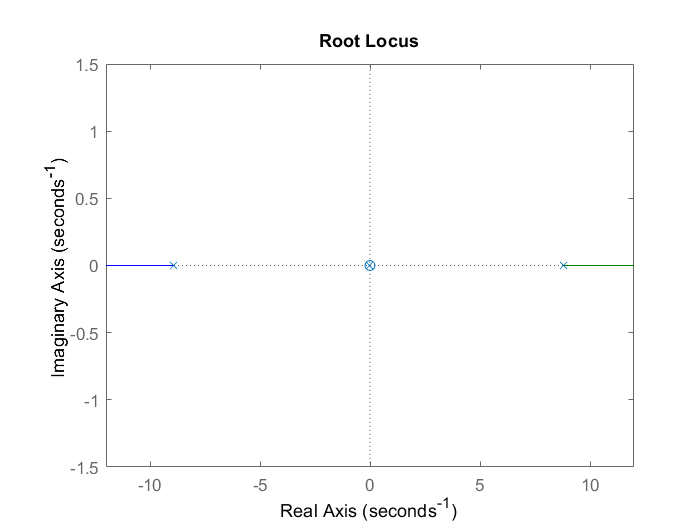

rlocus(G*H)
xlim([-12 12])

disp("Lag")

Lag


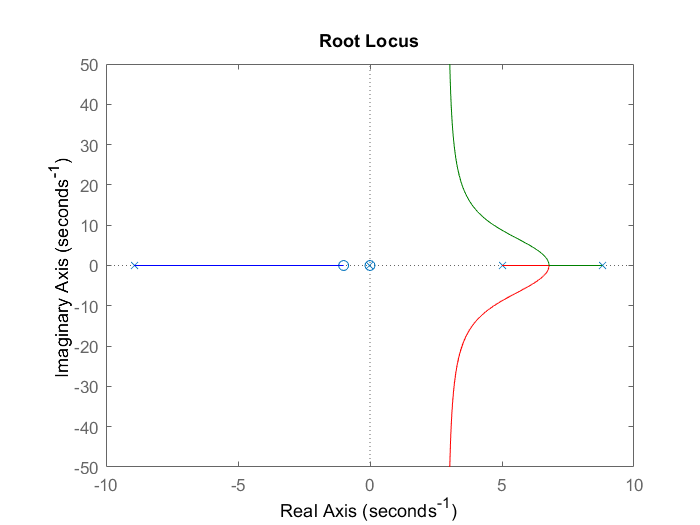

rlocus(D1*G*H)

disp("Lead")

Lead


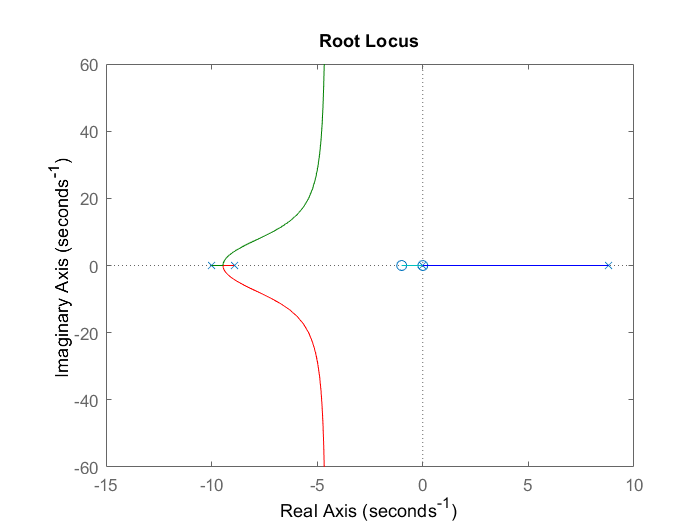

rlocus(D2*G*H)

disp("Lead-Lag")

Lead-Lag


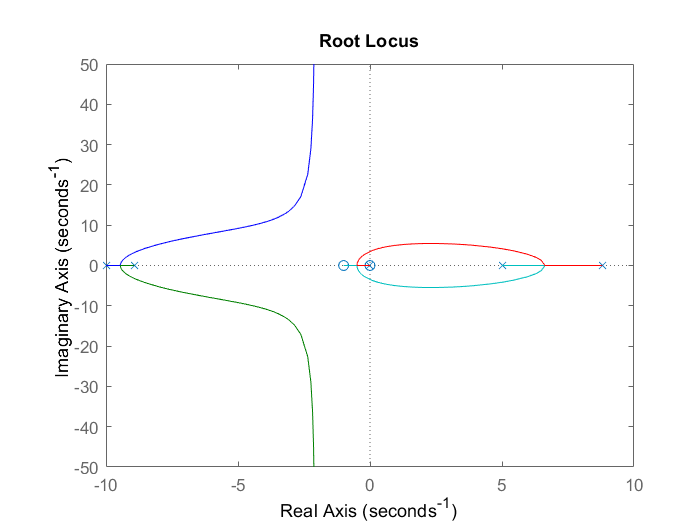

rlocus(D*G*H)
xlim([-10 10])

## Nyquist

disp("Nyquist")

Nyquist


p = pole(T1)

p =   -7.0512 + 6.7024i
  -7.0512 - 6.7024i
   4.4820 + 4.6314i
   4.4820 - 4.6314i
  -0.0026 + 0.0000i


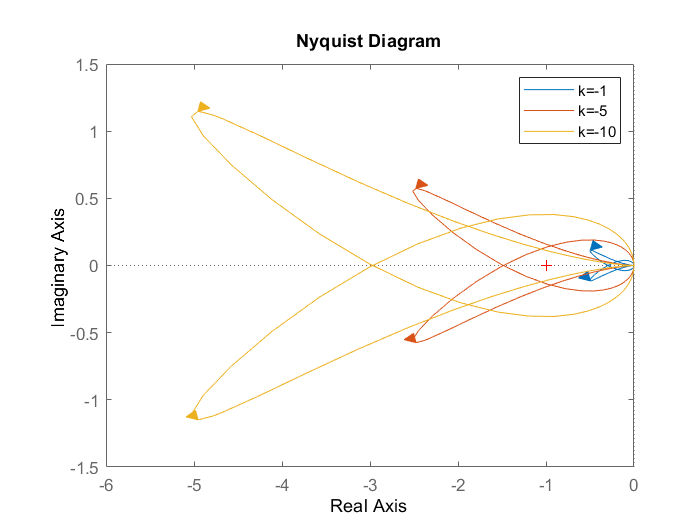

nyquistplot(D*G, 5*D*G, 10*D*G)
legend("k=-1", "k=-5", "k=-10")

## Final

k=-5

k = -5

D = k*((s+z1)*(s+z2))/((s+p1)*(s+p2))

D =
 
  -5 s^2 - 5.005 s - 0.005
  ------------------------
       s^2 + 5 s - 50
 
Continuous-time transfer function.



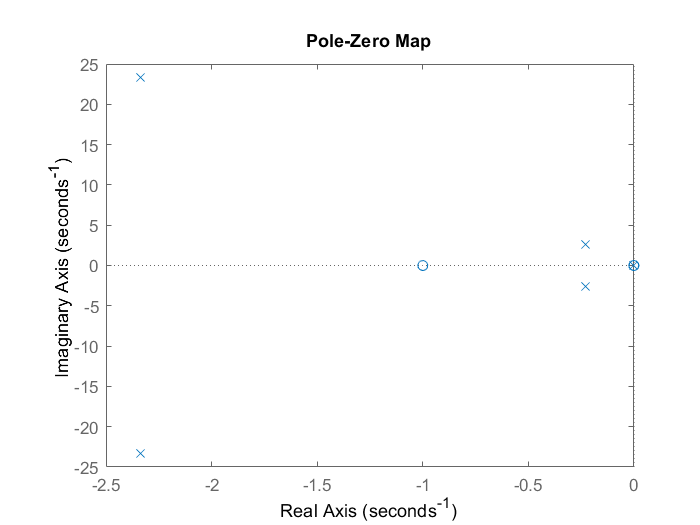

pzplot(feedback(D*G,H))

pole(feedback(D*G,H))

ans =   -2.3388 +23.3629i
  -2.3388 -23.3629i
  -0.2304 + 2.6601i
  -0.2304 - 2.6601i
  -0.0026 + 0.0000i
